# Baseline metabolic fluxes

Author: Scott Campit

## Summary

This module computes metabolic fluxes for each demand reaction from the unconstrained eGEM model to evaluate how it performs without any other omics data imposed on it.

% Initialize metabolic modeling components
clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.26.2).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

load 07132020.mat;

% Set up objective function
eGEM.c = zeros(size(eGEM.c));
eGEM.c(string(eGEM.rxns) == 'biomass_objective') = 1;

% Set methionine lower bound to a really small number
[~, pos] = ismember({'EX_met_L_e'}, eGEM.rxns);
eGEM.lb(pos) = -0.5;

% Set up hyperparameters for the linear programming section
hyperparams.eps  = [];
hyperparams.kap  = [];
hyperparams.rho  = [];
hyperparams.mode = true;
hyperparams.eps2 = [];
hyperparams.kap2  = [];
hyperparams.pfba = true;

% Activity coefficient for demand reactions
epsilon = 0.0625;

## Load gene expression data

This module uses RNASeq data from the CCLE.

fileName = '/home/scampit/Data/Expression/RNASeq/CCLE/MappedRNASeq.xlsx';
df = readcell(fileName, 'Sheet', 'BiGG');

### Process gene expression data

% Get mapping data
map = string(df(2:end, 1:4));
df(:, 1:4) = [];

% Get string data
genes = df(1, :);
df(1, :) = [];

% Turn missing to NaN;
data = df;
mask = cellfun(@ismissing, data);
data(mask) = {NaN};

% Get numerical data
new_data = cell2mat(data);

### Standardize Gene Expression Data

% Standardize data and get p-value
mu = nanmean(new_data, 'all');
sigma = nanstd(new_data, [], 'all');

Zdata = (new_data - mu) ./ sigma;
pvalue = normpdf(Zdata);

mask = Zdata

mask =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.2361       NaN   -0.2503   -0.2739   -0.2503   -0.2503   -0.2758   -0.2753   -0.2739   -0.2739   -0.2782       NaN   -0.2782   -0.2782   -0.2782   -0.1369    0.1041    0.1041    0.1041   -0.2267   -0.2125   -0.2125   -0.1416   -0.2314   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.2692   -0.2456   -0.2758   -0.2503   -0.1652   -0.2030   -0.2408   -0.2597   -0.2314   -0.1983   -0.2692   -0.2692    0.1324    0.1324       NaN   -0.2408   -0.1652   -0.2777   -0.2078   -0.2408  

mask(pvalue < 0.05) = NaN;

ids = eGEM.genes;
[~, ia, ib] = intersect(ids, genes);
final_df = mask(:, ib);
genes = genes(ib);
final_df(final_df > 0) = 1;
final_df(final_df < 0) = -1;

clear df data new_data mask Zdata

### Compute WT fluxes

% Get list of demand reactions from eGEMM
pos = [3770, 3771, 3773:3814];
dm_reactions = string(eGEM.rxns(pos))'

dm_reactions = 1×44 string array
  Columns 1 through 4

    "DM_bulk_methylation"    "DM_bulk_acetylation"    "DM_KACn"    "DM_KACc"

  Columns 5 through 9

    "DM_KMe1"    "DM_KMe2"    "DM_KMe3"    "DM_dna5mtc_n"    "DM_atp_c"

  Columns 10 through 13

    "DM_h3k4me1_n"    "DM_h3k4me2_n"    "DM_h3k4me3_n"    "DM_h3k4ac1_n"

  Columns 14 through 17

    "DM_h3k9me1_n"    "DM_h3k9me2_n"    "DM_h3k9me3_n"    "DM_h3k9ac1_n"

  Columns 18 through 21

    "DM_h3k27me1_n"    "DM_h3k27me2_n"    "DM_h3k27me3_n"    "DM_h3k27ac1_n"

  Columns 22 through 25

    "DM_h3k36me1_n"    "DM_h3k36me2_n"    "DM_h3k36me3_n"    "DM_h3k36ac1_n"

  Columns 26 through 29

    "DM_h3k79me1_n"    "DM_h3k79me2_n"    "DM_h3k79me3_n"    "DM_h3k79ac1_n"

  Columns 30 through 34

    "DM_peplys_n"    "DM_oaa_n"    "DM_cit_n"    "DM_met_n"    "DM_succ_n"

  Columns 35 through 39

    "DM_fum_n"    "DM_akg_n"    "DM_mal__L_n"    "DM_pyr_n"    "DM_ac_n"

  Columns 40 through 44

    "DM_fald_n"    "DM_amet_n"    "DM_

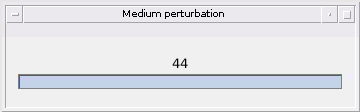

% Initialize data arrays
DE = cell(size(final_df, 1), 1);
flux = zeros(length(dm_reactions), size(final_df, 1));
soln = cell(size(final_df, 1), length(dm_reactions));
mdls = cell(size(final_df, 1), length(dm_reactions));
meta_data = cell(size(final_df, 1), length(dm_reactions));

wtbr = waitbar(0, '0', 'Name', 'Medium perturbation'); 
% Medium perturbation
for i = 1:length(dm_reactions)
    for j = 1:size(final_df, 1)
        % Get Differentially Expressed Genes
        DE{j}.name    = upper(map(j, 1));
        DE{j}.medium  = map(j, 3);
        DE{j}.culture = map(j, 4);
        DE{j}.tissue  = map(j, 2);
        DE{j}.upreg   = genes(final_df(2, :) == 1);
        DE{j}.downreg = genes(final_df(2, :) == -1);
        upgenes = DE{j}.upreg;
        downgenes = DE{j}.downreg;
        
        % Make medium model
        mediumModel = addMediumConstraints(eGEM, map(j, 3));
        mediumModel.c(pos(i)) = epsilon;
        
        % Compute flux using iMAT 
        [ConstrainedModel, solution] = CFR(mediumModel, hyperparams, ...
            DE{j}.upreg, DE{j}.downreg);
        
        % Store everything here
        flux(i, j) = solution.x(pos(i));
        %soln{j, i} = solution;
        %mdls{j, i} = ConstrainedModel;
        meta_data{j, i} = DE;
    end
    waitbar(i/length(dm_reactions), wtbr, sprintf('%d', i))
end